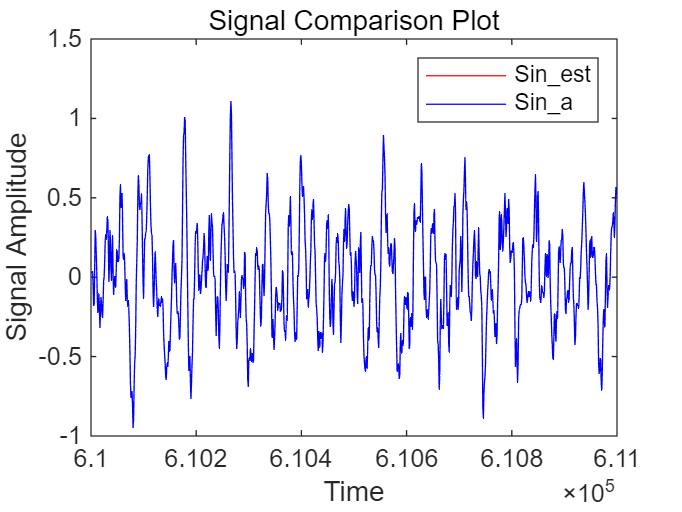

load("Hw2a.mat");

%% 初始化参数

[N, M] = size(Sin_a);         % 输入信号 Sin 和参考噪声 Sn_ref 的大小 (N: 时长, M: 声道数)
mu = 0.01;                  % 步长因子
Steps_Num_Adapter = 512;     % 适配器阶数（滤波器长度）

Adapter = zeros(Steps_Num_Adapter, M);    % 初始化滤波器参数
e = zeros(1, M);                          % 初始化误差信号

%% LMS 自适应滤波算法主循环

for n = 1:N
    w_hat = zeros(1, M);                 % 滤波器输出（估计噪声）

    for col = 1:M
        for i = 1:Steps_Num_Adapter
            if (n + 1 - i) > 0
                w_hat(col) = w_hat(col) + Adapter(i, col) * Sn_ref_a(n + 1 - i, col);
            end
        end
    end

    % 计算误差信号
    for col = 1:M
        e(col) = Sin_a(n, col) - w_hat(col);   % 被噪声污染的信号减去估计噪声
    end

    % 更新滤波器参数（适配器）
    if n > 1
        for col = 1:M
            for i = 1:Steps_Num_Adapter
                if (n - i) > 0
                    Adapter(i, col) = Adapter(i, col) + mu * 2 * e(col) * Sn_ref_a(n - i, col);
                end
            end
        end
    end
end

%% 滤波器输出估计与恢复信号计算

w_hat_squence = zeros(N + Steps_Num_Adapter - 1, M);   % 存储每个通道的卷积结果
Sin_est = zeros(N, M);                                 % 存储去噪后的信号

for col = 1:M
    w_hat_squence(:, col) = conv(Sn_ref_a(:, col), Adapter(:, col));
    Sin_est(:, col) = Sin_a(:, col) - w_hat_squence(1:N, col);
end

%% 可视化对比

figure(1);
plot(Sin_est(:,2), 'r');  % 绘制去噪信号，红色线
hold on;
plot(Sin_a(:,2), 'b');    % 绘制原始信号，蓝色线
hold off;

legend('Sin\_est', 'Sin\_a');
title('Signal Comparison Plot');
xlabel('Time');
ylabel('Signal Amplitude');
xlim([610000, 611000]);  % 设置横轴范围

sound(Sin_est, fs);
